Jeremy Primus

MECH532

HW9

% Data initialization
SiC_A = [497 291 493 605 511 524 327 484 394 448 511 497 426 345 358 287 412 466 493 592];
SiC_B = [421 690 556 573 618 609 690 654 618 645 591 739 739 703 569 685 708 573 717 676];
SiC_C = [466 618 529 627 564 564 573 394 618 493 511 475 618 493 591 627 618 600 645 614];
P = [SiC_A; SiC_B; SiC_C];
L1 = 20e-3;
L2 = 40e-3;
b = 4e-3;
d = 3e-3;
% calculate max stress
M = P*L1/2;                 % calculate moment
MOR = 6*M/(b*d^2);          % modulus of rupture
MaxStressMPa = MOR/1e6;     % convert to MPa
% SiC-A plot
figure()
histogram(MaxStressMPa(1,:),8,'Normalization', 'cdf')
ylabel('Failure Probability')
xlabel('Max Stress (MPa)')
title('SiC-A')

if we take $\sigma_u =0$, we can fit the failure distribution to a Weibull distribution with two parameters which describe the specimens.

pdA = fitdist(MaxStressMPa(1,:)', 'Weibull')

pdA =   WeibullDistribution

  Weibull distribution
    A = 806.752   [745.982, 872.473]
    B =  5.8947   [4.16801, 8.33672]


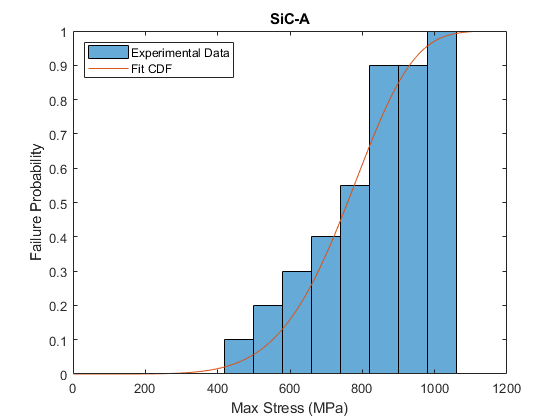

A_cdf = cdf(pdA, 0:1100);
hold on
plot(A_cdf)
legend('Experimental Data','Fit CDF', 'Location', 'northwest')

% SiC-B plot
figure()
histogram(MaxStressMPa(2,:),8,'Normalization', 'cdf')
ylabel('Failure Probability')
xlabel('Max Stress (MPa)')
title('SiC-B')
pdB = fitdist(MaxStressMPa(2,:)', 'Weibull')

pdB =   WeibullDistribution

  Weibull distribution
    A = 1117.12   [1070.95, 1165.28]
    B = 10.8915   [7.61869, 15.5703]


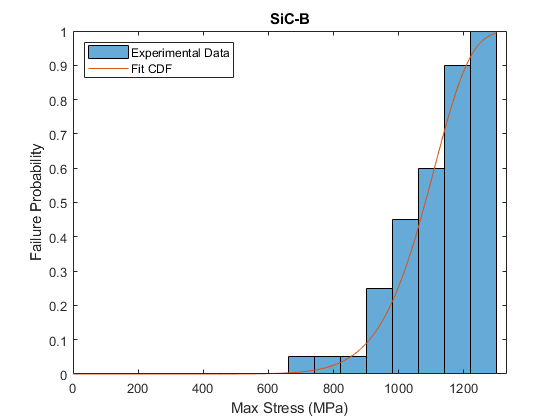

B_cdf = cdf(pdB, 0:1300);
hold on
plot(B_cdf)
legend('Experimental Data','Fit CDF', 'Location', 'northwest')

% SiC-C plot
figure()
histogram(MaxStressMPa(3,:),8,'Normalization', 'cdf')
ylabel('Failure Probability')
xlabel('Max Stress (MPa)')
title('SiC-C')
pdC = fitdist(MaxStressMPa(3,:)', 'Weibull')

pdC =   WeibullDistribution

  Weibull distribution
    A = 983.504   [944.039, 1024.62]
    B = 11.1999   [7.71671, 16.2555]


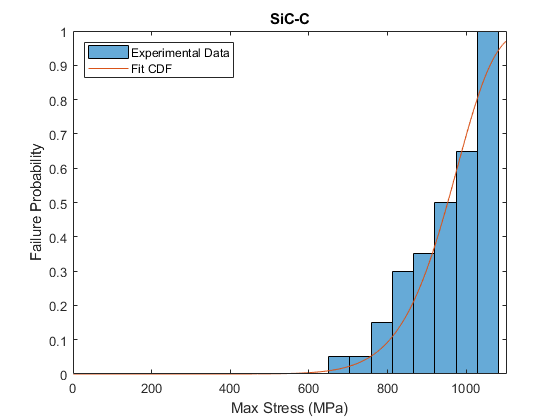

C_cdf = cdf(pdC, 0:1100);
hold on 
plot(C_cdf)
legend('Experimental Data','Fit CDF', 'Location', 'northwest')

Although I understand an approach for linear regression was described in the notes, this is a simpler more direct solution to the requested answers.  The failure probability distribution is given by histogramming the data.  Fitting that distribution allowed me to obtain the parameters for a CDF.  In each case, $\sigma_o$is given by A, while the Weibull modulus, *m*, is given by B.  In both cases, the 95% confidence interval is given.